clear all
clc
close all

[T1,X1] = BVS(3);

A =    -1.2857    1.0000
    0.2857   -1.2857


[T2,X2] = BVS(5);

A =    -1.5714    1.0000         0         0
    0.5714   -1.5714    1.0000         0
         0    0.5714   -1.5714    1.0000
         0         0    0.5714   -1.5714


[T3,X3] = BVS(10);

A =    -1.7857    1.0000         0         0         0         0         0         0         0
    0.7857   -1.7857    1.0000         0         0         0         0         0         0
         0    0.7857   -1.7857    1.0000         0         0         0         0         0
         0         0    0.7857   -1.7857    1.0000         0         0         0         0
         0         0         0    0.7857   -1.7857    1.0000         0         0         0
         0         0         0         0    0.7857   -1.7857    1.0000         0         0
         0         0         0         0         0    0.7857   -1.7857    1.0000         0
         0         0         0         0         0         0    0.7857   -1.7857    1.0000
         0         0         0         0         0         0         0    0.7857   -1.7857


[T4,X4] = BVS(15);

A =    -1.8571    1.0000         0         0         0         0         0         0         0         0         0         0         0         0
    0.8571   -1.8571    1.0000         0         0         0         0         0         0         0         0         0         0         0
         0    0.8571   -1.8571    1.0000         0         0         0         0         0         0         0         0         0         0
         0         0    0.8571   -1.8571    1.0000         0         0         0         0         0         0         0         0         0
         0         0         0    0.8571   -1.8571    1.0000         0         0         0         0         0         0         0         0
         0         0         0         0    0.8571   -1.8571    1.0000         0         0         0         0         0         0         0
         0         0         0         0         0    0.8571   -1.8571    1.0000         0         0         0         0         0         0
         

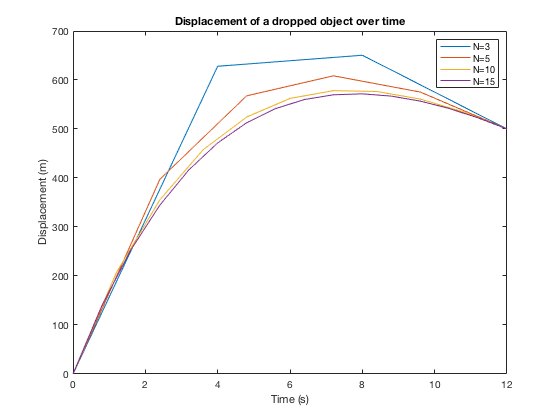


plot(X1,T1)
hold on
plot(X2,T2)
hold on
plot(X3,T3)
hold on
plot(X4,T4)
xlabel("Time (s)")
ylabel("Displacement (m)")
title("Displacement of a dropped object over time")
legend("N=3", "N=5", "N=10", "N=15")

function [t,x] = BVS(n)
A = zeros(n-1, n-1);
v = zeros(1, n-1);

dt = 12/n;
l = 12.5*dt/70;

v(:) = -2+l;

v1 = zeros(1,n-2);
v1(:) = 1;

v2 = zeros(1,n-2);
v2(:) = 1-l;

A = diag(v) + diag(v1,1) + diag(v2,-1)

b = zeros(1,n-1);
b(:) = -9.81*((12/n)^2);
b(n-1) = -9.81*((12/n)^2)-500;
b = b';

t = A\b;
t = [0 t(:)' 500];
x = linspace(0,12,n+1);
end